# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\Luke\Simon\RawData_All'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5 ;                                            % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = false;                                                                  % Continue to next step when current step is done?
Deci.PCom               = false;                                                      % Activates Parallel Computing for PP and Analysis only
Deci.Folder.Version     = ['C:\Users\User\Desktop\Luke\Simon\ProcessedData'];        % Output Folder Directory

## 1. Trial Definitions 

Deci.DT.Type = 'Simon_Polymerase';
Deci.DT.Starts     = {17};                                                                      % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {18};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[14 15] [16 45 46 19] [300 400] [37 38] [31 34] [23 24]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [12 30 22];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq                                                               % Time of Interest, be sure to include larger window for freq

Deci.DT.Displace.AddLocks = true; 
Deci.DT.Displace.Markers = {[14 15] [16 45 46 19] [300 400] [37 38] [31 34]};
Deci.DT.Displace.Duration = 1;
Deci.DT.Displace.Num = -1;

Deci.DT.Block.Markers   = {40};
Deci.DT.Block.Bisect = true;

## 2. PreProcessing Steps

Deci.PP.filter.bpfreq = [.5 80];
Deci.PP.filter.bpfilter = 'yes';
Deci.PP.filter.detrend = 'yes';

Deci.ICA.bpfreq = [1 30];
Deci.ICA.Automatic = false;

## 3. Artifact Rejection

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 1.5];
Deci.Art.RT.minlength = 200;
Deci.Art.RT.locks = [2 1];

Deci.Art.AddComponents =  false;

## 4. Analysis

if Deci.Step > 3
    Deci.DT.Markers    = {[14 15] [300 400] [31 34] [1014 1015] [1300 1400] [1031 1034]};                    
end

%LockTypes = {'Simon_Cor' 'Simon_Con' 'Simon_Side' 'Simon_Contra'};
%LockTypes = {'Simon_ConCor' 'Simon_ContraCor'};
%LockTypes = {'Simon_ContraCor'};
%Locktypes = {'Simon_Congruence' 'Simon_Laterality'};
%Locktypes = {'Simon_Cor' 'Simon_Congruence' 'Simon_ConCor'};
Locktypes = {'SimonConn_Cor'};
%Locktypes = {'Simon_Congruence'}

%Locktypes = {'Simon_CongruenceDuplets' 
%Locktypes = {'Simon_CorrectnessDuplets'}
%Locktypes = {'Simon_CongruencexCorrectnessDuplets'}
%Locktypes = {'Simon_CorrectCongruenceDuplets'}

## 5. Plotting

## ** 6. Run**

Running Deci for 25 subjects
 
----------------------
 
Plotting TotalPower
Loading Plottor for Subject #1: Simon_EEGTest1_001PS
Loading Plottor for Subject #2: Simon_EEGTest1_002PS
Loading Plottor for Subject #3: Simon_EEGTest1_007PS
Loading Plottor for Subject #4: Simon_EEGTest1_008CG
Loading Plottor for Subject #5: Simon_EEGTest1_011PS
Loading Plottor for Subject #6: Simon_EEGTest1_015CG
Loading Plottor for Subject #7: Simon_EEGTest1_018PS
Loading Plottor for Subject #8: Simon_EEGTest1_026CG
Loading Plottor for Subject #9: Simon_EEGTest1_032CG
Loading Plottor for Subject #10: Simon_EEGTest1_046PS
Loading Plottor for Subject #11: Simon_EEGTest_002CG
Loading Plottor for Subject #12: Simon_EEGTest_004PS
Loading Plottor for Subject #13: Simon_EEGTest_007CG
Loading Plottor for Subject #14: Simon_EEGTest_009PS
Loading Plottor for Subject #15: Simon_EEGTest_010CG
Loading Plottor for Subject #16: Simon_EEGTest_011CG
Loading Plottor for Subject #17: Simon_EEGTest_013PS
Loading Plottor for Su

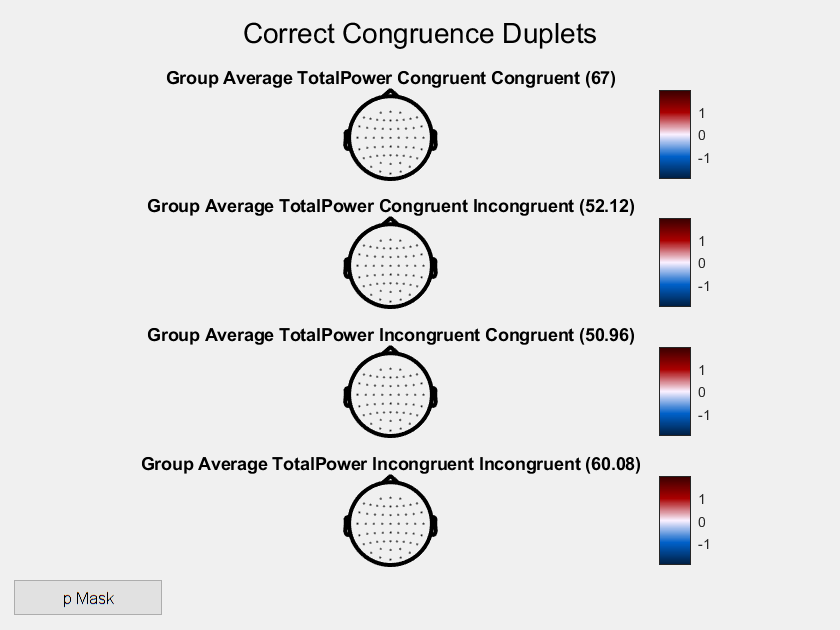

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


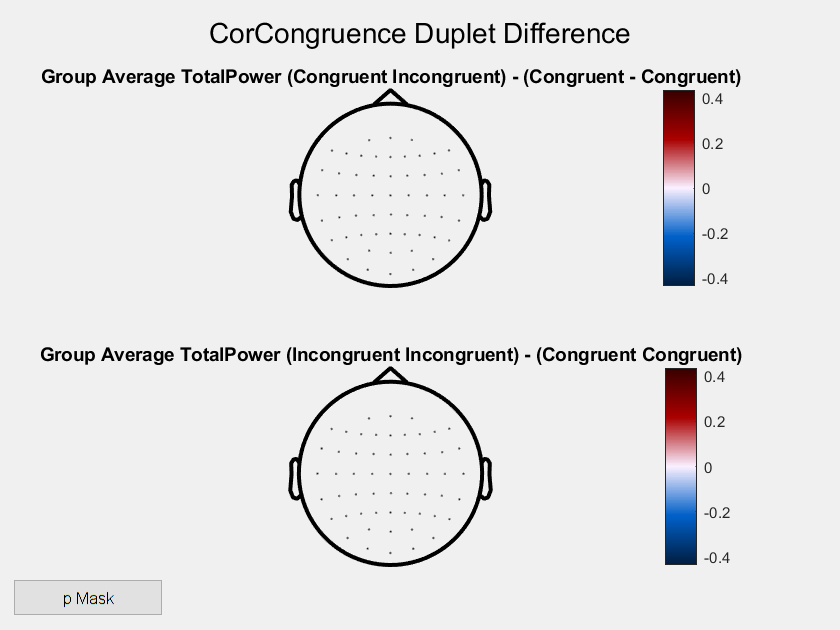

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


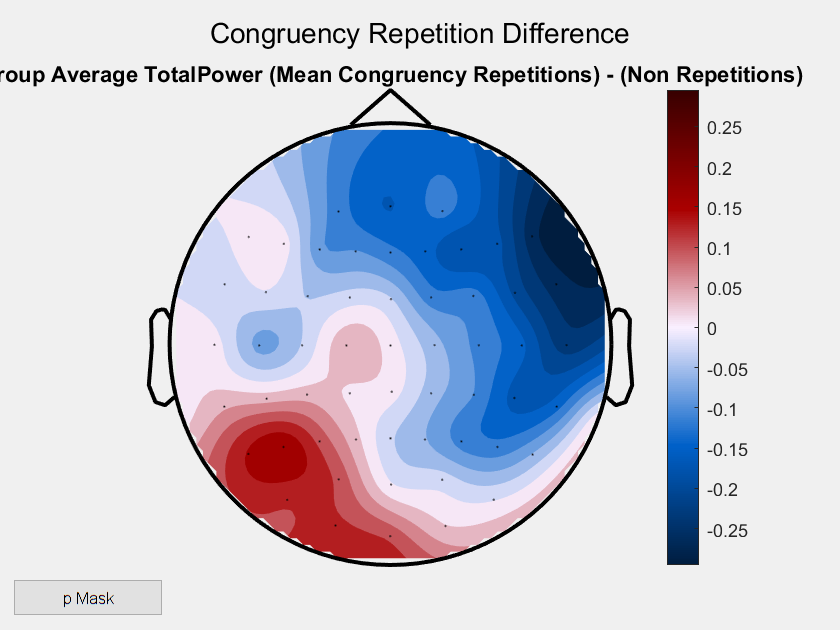

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


if Deci.Step == 4
    for AnalysisLocks = Locktypes
        Deci_Wavelet;;
        
        Deci.Analysis.Freq.foi           = exp(linspace(log(1),log(60),40));                           % Frequency of Interest
        Deci.Analysis.Freq.width         = exp(linspace(log(3),log(13),40));                                                         % Width
        Deci.Analysis.Freq.Toi           = [-.5 1.5];  
        
        eval(AnalysisLocks{1})
        Deci.SubjectList        = 'gui';
       
        Deci.Analysis.Freq.do  = false;
        Deci.Analysis.ERP.do  = false;
        Deci_Backend(Deci);
        
    end
else
    
    Simon_CongruenceDuplets;
    
    Deci.Run.Behavior = false;
    Deci.Run.Freq =true;
    Deci.Run.ERP =false;
    Deci.Run.CFC = false;
    Deci.Run.Extra = false;
    
    
    Deci.Plot.BslRef = 'Stim Onset';
    Deci.Plot.Lock =   'Next Stim';
    
    Deci.Plot.GrandAverage = true;
    
    Deci.Plot.Freq.Topo.do    =true;
    Deci.Plot.Freq.Topo.Foi     = [4 9];                   % Frequency of Interest
    Deci.Plot.Freq.Topo.Toi     = [.25 .5];                   % Time of Interest
    Deci.Plot.Freq.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest
    
    Deci.Plot.Freq.Square.do  =false;
    Deci.Plot.Freq.Square.Foi     = [3 inf];                 % Frequency of Interest
    Deci.Plot.Freq.Square.Toi     = [];                   % Time of Interest
    Deci.Plot.Freq.Square.Channel = ['Reinhart-All'];                % Channel of Interest
    
    Deci.Plot.Freq.Wire.do    =false;
    Deci.Plot.Freq.Wire.Foi     =   [9 13];          % Frequency of Interest
    Deci.Plot.Freq.Wire.Toi     = [-.5 0];                   % Time of Interest
    Deci.Plot.Freq.Wire.Channel = [{'PO7' 'PO8'}];              % Channel of Interest
    
    Deci.Plot.Freq.Bar.do    =false;
    Deci.Plot.Freq.Bar.Foi     = [13 21];                 % Frequency of Interest
    Deci.Plot.Freq.Bar.Toi     = [-.5 -.4];                   % Time of Interest
    Deci.Plot.Freq.Bar.Channel =  [{'PO7' 'PO8'}];            % Channel of Interest
    
    Deci.Plot.Freq.Type    = 'TotalPower';
    
    if  strcmpi(Deci.Plot.BslRef, 'Rsp Onset')
        Deci.Plot.Freq.Bsl     = [-.5 -.3];
    else
        Deci.Plot.Freq.Bsl     = [-.5 0];
    end
    
    %Luke(1/11/20): Might change .BslRef, 'Rsp Onset' has been changed from [-.5 -.3] to [-.8 -.6]
   %and .BslRef (else) from [-.5 0] to [-.4
    %-.2] 
    
    
    if  Deci.Plot.Freq.Square.do
        Omnibus = true;
        
        
        if Omnibus == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Comp = 'Bsl';
            Deci.Plot.Stat.alpha = .01;
            Deci.Plot.Stat.correctm = 'fdr';
            Deci.Plot.Freq.BslType = 'db';
            Deci.Plot.Stat.FPlots =  false;
        else
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Randomize Permutation';
            Deci.Plot.Stat.alpha = .05;
        end
        Deci.Plot.Stat.FPlots =  false;
    end
    
    if Deci.Plot.Freq.Topo.do 
        Perma = true;
        
        if Perma == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Randomize Permutation';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
        end
    end
    
    if Deci.Plot.Freq.Wire.do
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Anova/T-test';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
    end
        
    
    if Deci.Plot.Freq.Bar.do
        Deci.Plot.Stat.do = false;
    end
    
     if Deci.Plot.Freq.Wire.do
        Deci.Plot.Stat.do = false;
    end
    
    Deci_Backend(Deci);
end